# **ECON 310: Dynamic Macroeconomics**

### **Spring 2025**

### **Fulbright University Vietnam**

%{

    run_vfi_sgml.mlx
    ----------------
    This code solves the stochastic growth model with endogenous labor supply using value function iteration.

%}

## Model: Stochastic Growth Model with Government Sector.

The social planner's problem is


$$\underset{\{c_t\}_{t=1}^{\infty},\{k_{t+1}\}_{t=1}^{\infty}}{\text{max }} \mathbb{E}_0\sum_{t=1}^\infty \beta^{t} \left[\frac{c_t^{1-\sigma}}{1-\sigma} +\frac{g_t^{1-\sigma}}{1-\sigma} \right] \text{ ,}$$


 
$$\begin{array}{r l} \text{s.t. } y_t = c_t+i_t \end{array} \ ,$$


 
$$\begin{array}{r l} y_t = A_t k_t^{\alpha}\end{array} \ ,$$


 
$$\begin{array}{r l} k_{t+1} = (1-\delta)k_t+ i_t \end{array} \ ,$$



$$\begin{array}{r l}c_t + i_t = (1-\tau_t^k)r_tk_t+(1-\tau_t^n)w_tn_t+\delta\tau_t^kk_t+g_t \end{array} \ ,$$



$$\begin{array}{r l}g_t = \tau_t^k r_tk_t+\tau_t^nw_tn_t-\delta\tau_t^kk_t \end{array} \ ,$$


 
$$\begin{array}{r l} \text{log}(A_{t+1}) = \mu + \rho\text{log}(A_t) + \epsilon_{t+1} \end{array} \ ,$$


 
$$\begin{array}{r l} n_t =1\end{array} \ ,$$



$$c_t > 0,  k_t > 0 \ ,$$


where $|\rho| < 1$, $\epsilon_{t+1}\sim\mathcal{N}(0,\sigma^2_{\epsilon})$, and the constraints are for $t = 1, 2, ...,$. 

## Set up directories and paths.

clc
clear
close all

main = strcat('C:\Users\Do Thu An\OneDrive\Desktop\Dynamic Macroeconomics\Problem sets\Dynamic-Macroeconomics\PS1_Code\Matlab'); % Project Folder.
cd (strcat(main)) % Set project folder as current working directory.

addpath(genpath(main)) % Add all subfolders in current working directory to path. Note: Make sure file names are unique.
figout = strcat(main,'/output/figures/'); % Folder for figures.
texout = strcat(main,'/output/tables/'); % Folder for txt outputs.

fprintf('The directory is %s \n\n',main)

The directory is C:\Users\Do Thu An\OneDrive\Desktop\Dynamic Macroeconomics\Problem sets\Dynamic-Macroeconomics\PS1_Code\Matlab 



## Set the parameters and generate the state space.

Calls: model.m.

As before, we cannot directly compute the steady state capital because of the productivity fluctuations, but we can still build the grid for $k_t$ around the deterministic steady state.

par = model.setup; % Set parameters.
par = model.gen_grids(par); % Generate the state space.

## Solve the model using Value Function Iteration.

Calls: solve.m, and model.m.

t = cputime;
sol = solve.grow(par); % Solve the model using Value Function Iteration.

------------Beginning Value Function Iteration.------------

Iteration: 25.
Iteration: 50.
Iteration: 75.
Iteration: 100.
Iteration: 125.
Iteration: 150.
Iteration: 175.
Iteration: 200.
Iteration: 225.
Iteration: 250.
Iteration: 275.
Iteration: 300.
Iteration: 325.
Iteration: 350.
Iteration: 375.

Converged in 399 iterations.

------------End of Value Function Iteration.------------


fprintf('\nModel solved in %0.4f seconds.\n',cputime-t)


Model solved in 80.7031 seconds.


## Simulate the model and plot the model functions and time series.

Calls: simulate.m and my_graph.m.

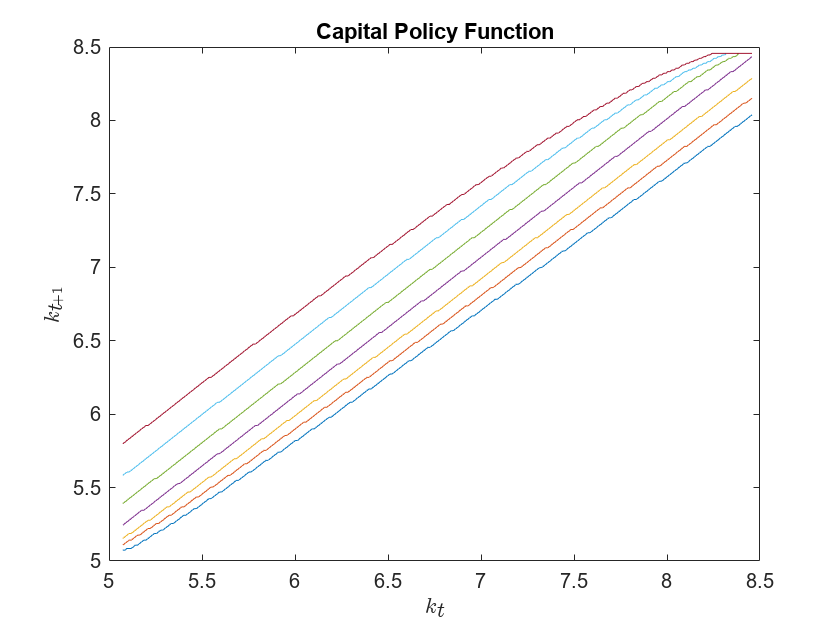

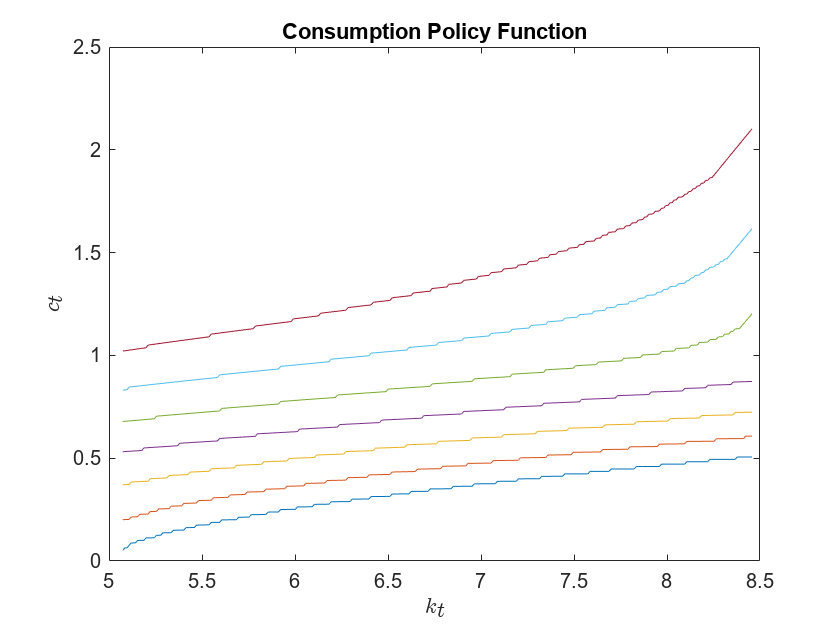

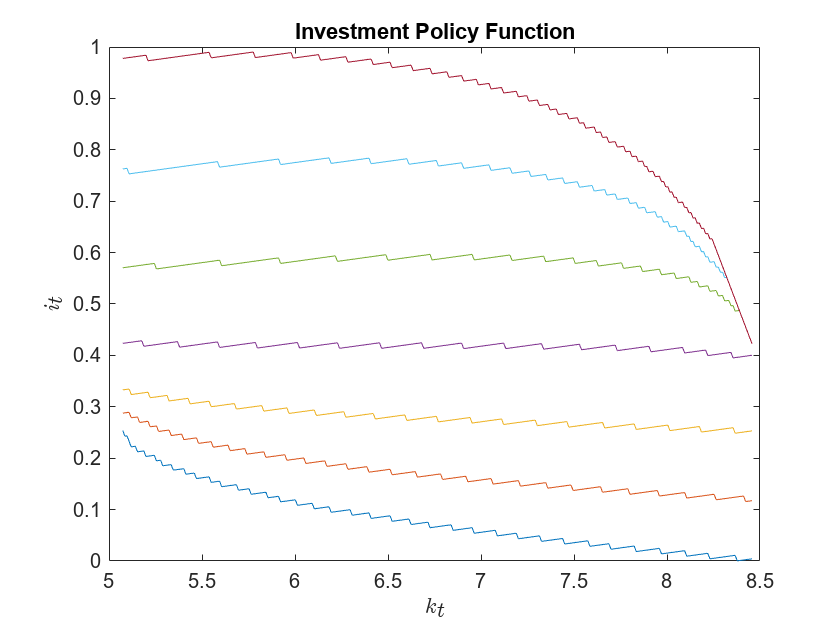

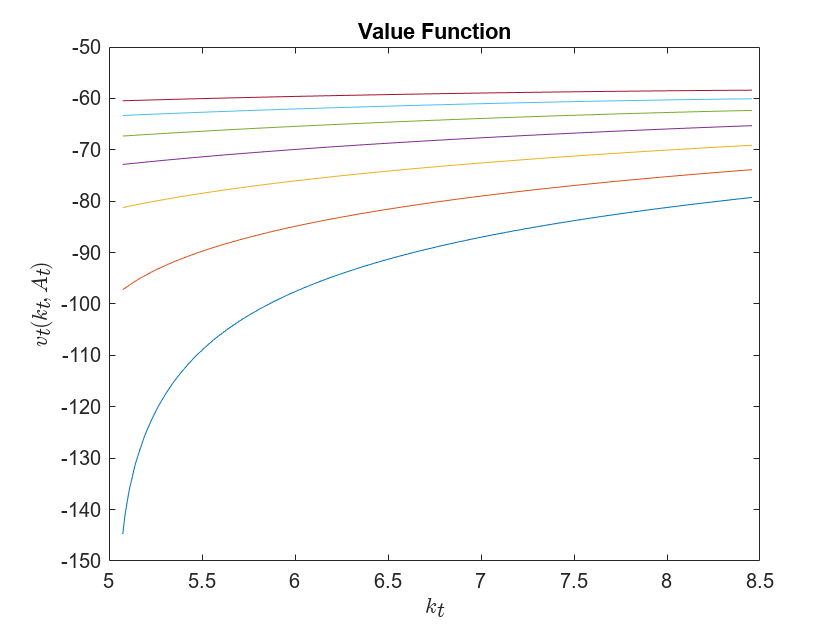

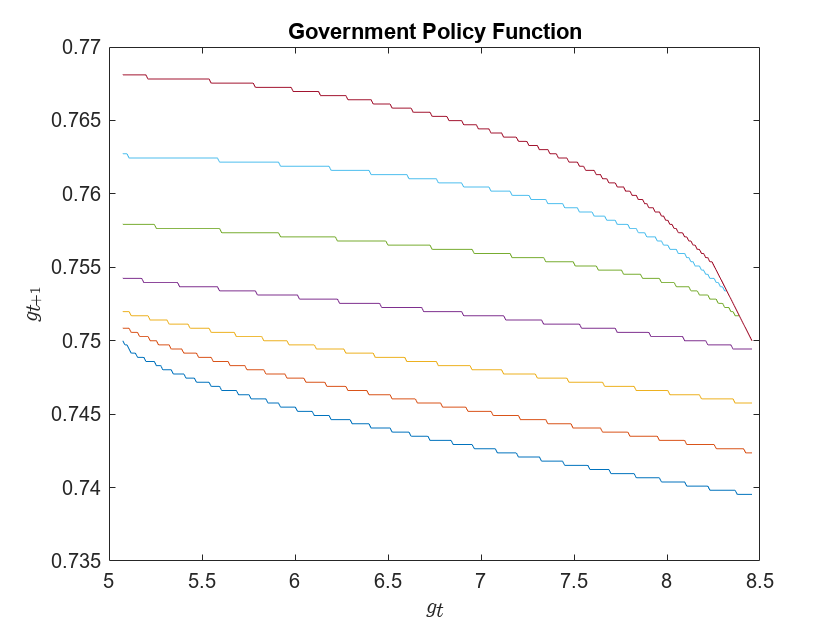

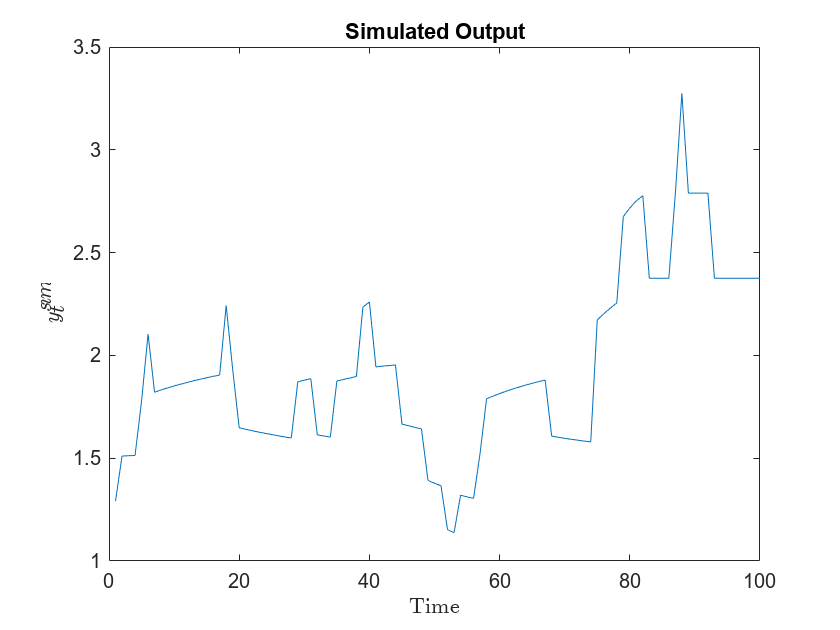

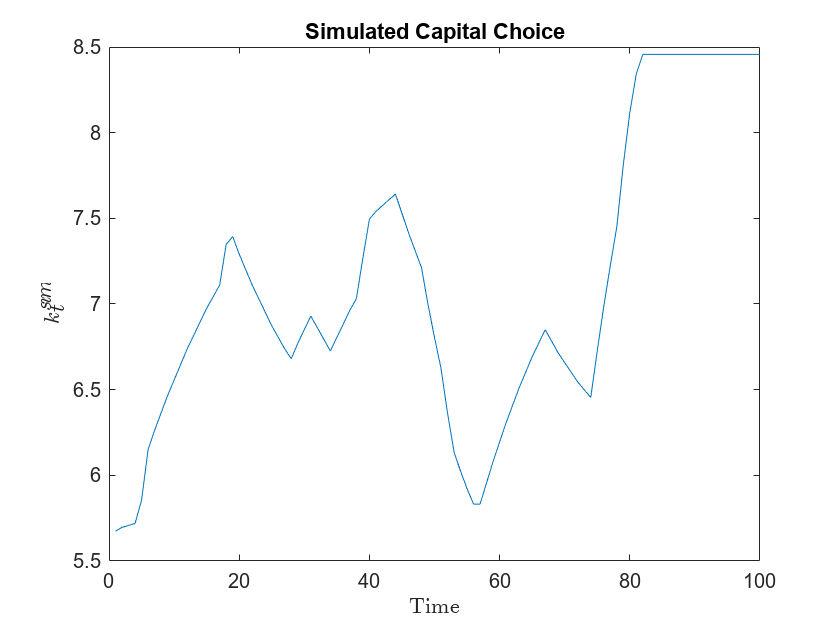

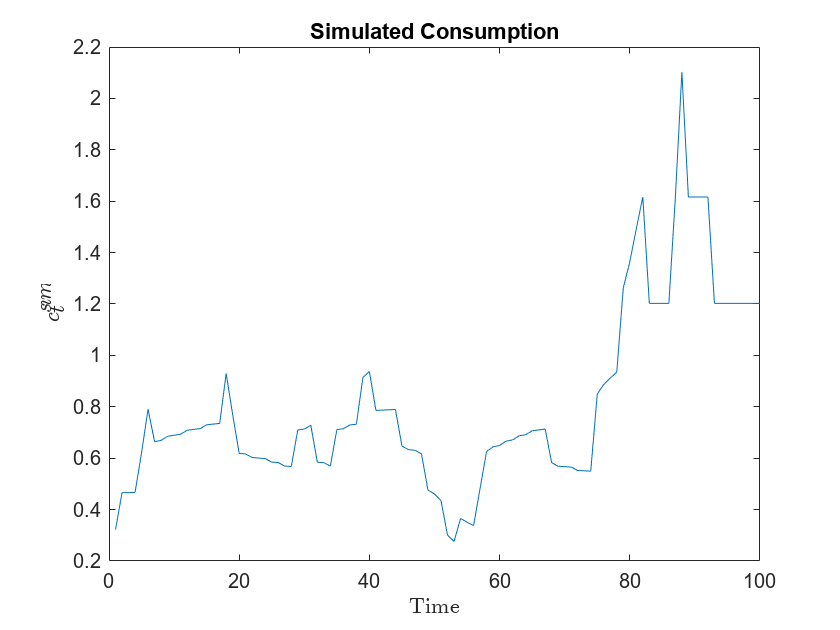

sim = simulate.grow(par,sol); % Simulate the model.
my_graph.plot_policy(par,sol,sim,figout) % Plot the model functions and time series.

## Analysis.

To check the validity of the model, we compute statistics of interest and see how the data line up. In some cases, these are explicitly targeted by adjusting or estimating parameters that govern the behavior of the simulated data. In our case, we just set these exogenously from the literature, which in turn obtain these from data or estimation. The model differs from the literature so this model is off from the data, see Table 5.1 in Adda and Cooper.

% Compute the variables corresponding to data. The model assumes the data are detrended.
ysim = sim.ysim; % Output.
ksim = sim.ksim; % Capital Stock.
isim = sim.isim; % Investment.
csim = sim.csim; % Consumption.
gsim = sim.gsim; % Government.

% Std. Dev of variables relative to output.
cvar = sqrt(var(csim))/sqrt(var(ysim));
ivar = sqrt(var(isim))/sqrt(var(ysim));
gvar = sqrt(var(gsim))/sqrt(var(ysim));
kvar = sqrt(var(ksim))/sqrt(var(ysim));


fprintf('The Std. Dev of Capital Relative to Output is: %0.4f',kvar)

The Std. Dev of Capital Relative to Output is: 1.9528

fprintf('The Std. Dev of Consumption Relative to Output is: %0.4f',cvar)

The Std. Dev of Consumption Relative to Output is: 0.8271

fprintf('The Std. Dev of Investment Relative to Output is: %0.4f',ivar)

The Std. Dev of Investment Relative to Output is: 0.2890

fprintf('The Std. Dev of Government Relative to Output is: %0.4f',gvar)

The Std. Dev of Government Relative to Output is: 0.0070

## Apply real-time data for Vietnam

### Load the dataset

%% Import dataset
path = strcat("C:\Users\Do Thu An\OneDrive\Desktop\Dynamic Macroeconomics\Problem sets\Dynamic-Macroeconomics\PS1_Code\data.csv");
data = readtable(path)

data = 28×12 table
    Year    GDP_constant2015US__    GDPPerCapita_constant2015US__    GDPGrowthRate___    FDIInflow_BoP_US__    GrossFixedCapitalFormation_constant2015US__    GrossCapitalFormationGrowth___    GrossFixedCapitalFormation__OfGDP_    FinalConsumptionExpenditure_constant2015US__    Population_Total    ConsumptionPerCapita_constant2015US__    InvestmentPerCapita_constant2015US__
    ____    ____________________    _____________________________    ________________    __________________    ___________________________________________    ______________________________    __________________________________    ___________________________

### Exploratory data analysis (EDA)

disp(data.Properties.VariableNames)

  Columns 1 through 3

    {'Year'}    {'GDP_constant201…'}    {'GDPPerCapita_co…'}

  Columns 4 through 6

    {'GDPGrowthRate___'}    {'FDIInflow_BoP_U…'}    {'GrossFixedCapit…'}

  Columns 7 through 9

    {'GrossCapitalFor…'}    {'GrossFixedCapit…'}    {'FinalConsumptio…'}

  Columns 10 through 12

    {'Population_Total'}    {'ConsumptionPerC…'}    {'InvestmentPerCa…'}



%% Extract actual data & convert to log values
%% Real-world Capital & Government spending via tax rates are hard to collect (with low accuracy)
actual_t=  1:length(data.Year);       % Time
actual_i = log(data.InvestmentPerCapita_constant2015US__);      % Empirical investment
actual_c = log(data.ConsumptionPerCapita_constant2015US__);     % Empirical consumption
actual_y = log(data.GDPPerCapita_constant2015US__);                    % GDP per capita

%% Extract first 28 values of simulated data to match actual data length
sim_t = 1:28;
sim_ysim = sim.ysim(1:28);
sim_isim = sim.isim(1:28);
sim_csim = sim.csim(1:28);


### Visualize the empirical data vs simulated data

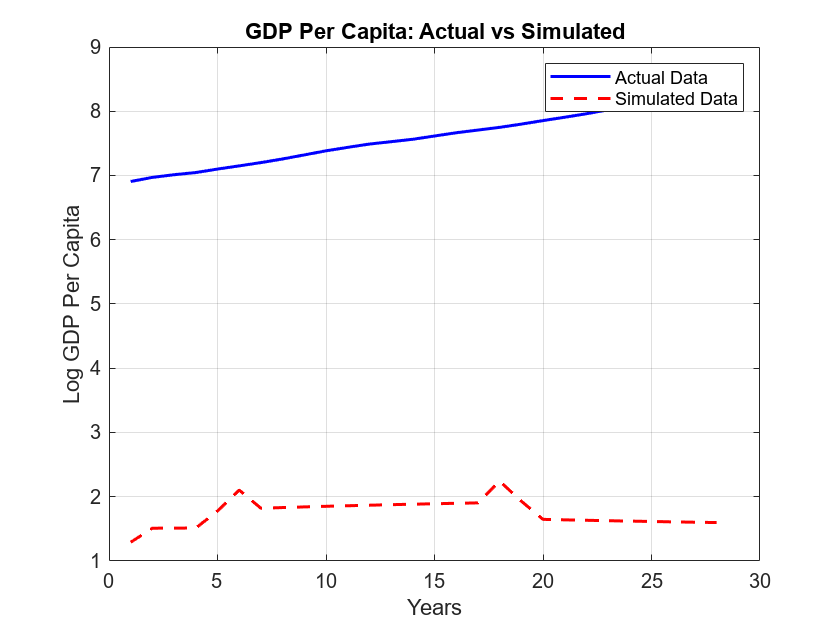

%% Plot actual vs. simulated GDP per capita
figure;
plot(actual_t, actual_y, 'b-', 'LineWidth', 1.5); % Actual data
hold on;
plot(sim_t, sim_ysim, 'r--', 'LineWidth', 1.5); % Simulated data (first 28 values)
title('GDP Per Capita: Actual vs Simulated');
xlabel('Years'); ylabel('Log GDP Per Capita');
legend('Actual Data', 'Simulated Data');
grid on;
saveas(gcf, fullfile(figout, 'gdp_comp.png'));

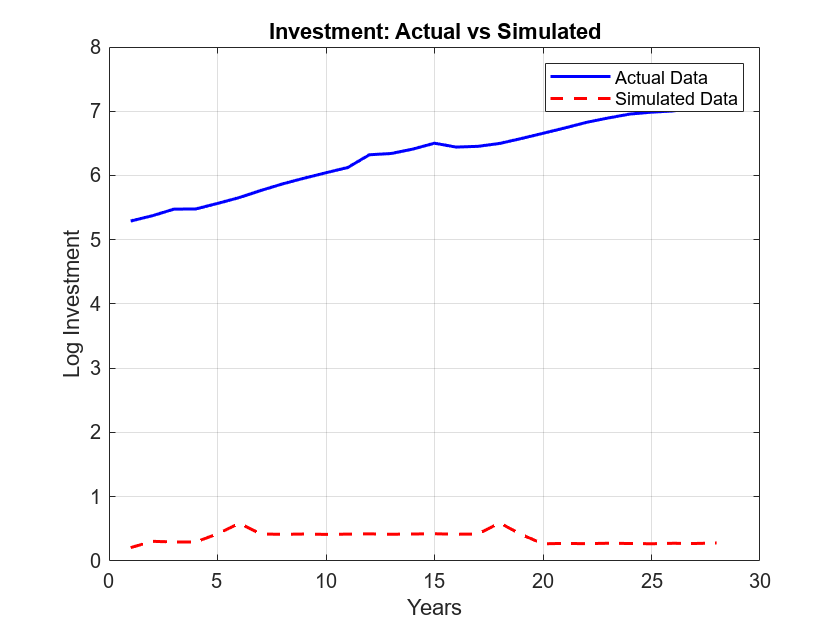

%% Plot Investment
figure;
plot(actual_t, actual_i, 'b-', 'LineWidth', 1.5); hold on;
plot(sim_t, sim_isim, 'r--', 'LineWidth', 1.5);
title('Investment: Actual vs Simulated');
xlabel('Years'); ylabel('Log Investment');
legend('Actual Data', 'Simulated Data');
grid on;
saveas(gcf, fullfile(figout, 'icomp.png'));

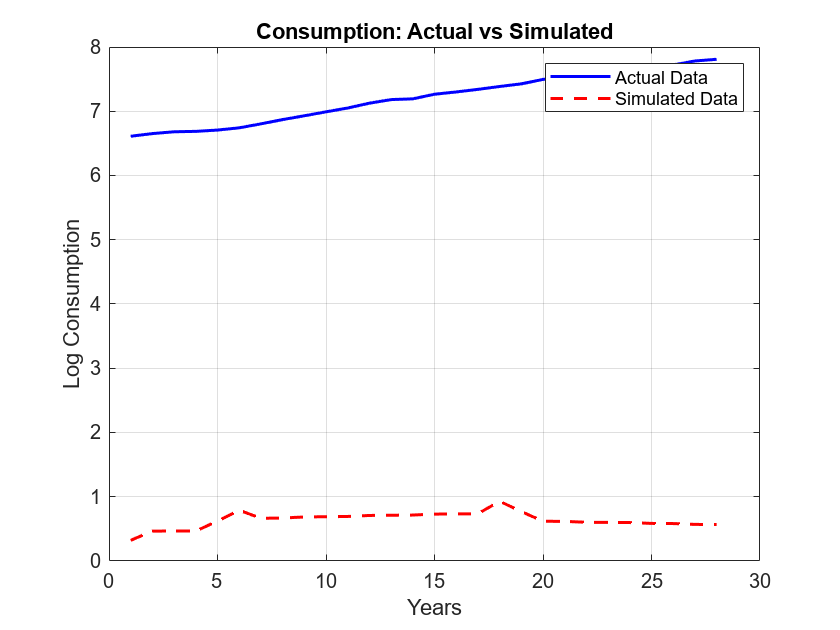

%% Plot Consumption
figure;
plot(actual_t, actual_c, 'b-', 'LineWidth', 1.5); hold on;
plot(sim_t, sim_csim, 'r--', 'LineWidth', 1.5);
title('Consumption: Actual vs Simulated');
xlabel('Years'); ylabel('Log Consumption');
legend('Actual Data', 'Simulated Data');
grid on;
saveas(gcf, fullfile(figout, 'ccomp.png'));

### Descriptive Statistics: Real vs Simulated data

%% Compute statistics for actual GDP per capita
min_actual_gdp = min(actual_y);
max_actual_gdp = max(actual_y);
mean_actual_gdp = mean(actual_y);
median_actual_gdp = median(actual_y);
std_actual_gdp = std(actual_y);

%% Compute statistics for simulated GDP per capita
min_sim_gdp = min(sim_ysim);
max_sim_gdp = max(sim_ysim);
mean_sim_gdp = mean(sim_ysim);
median_sim_gdp = median(sim_ysim);
std_sim_gdp = std(sim_ysim);

%% Create a table for GDP per capita
T_GDP = table({'Actual'; 'Simulated'}, ...
    [min_actual_gdp; min_sim_gdp], [max_actual_gdp; max_sim_gdp], ...
    [mean_actual_gdp; mean_sim_gdp], [median_actual_gdp; median_sim_gdp], ...
    [std_actual_gdp; std_sim_gdp], ...
    'VariableNames', {'Scenario', 'Min', 'Max', 'Mean', 'Median', 'StdDev'});

disp('Descriptive Statistics: GDP Per Capita');

Descriptive Statistics: GDP Per Capita


disp(T_GDP);

      Scenario        Min       Max       Mean     Median    StdDev 
    _____________    ______    ______    ______    ______    _______

    {'Actual'   }    6.9067    8.2323    7.5848    7.5892    0.40697
    {'Simulated'}     1.292    2.2432    1.7503    1.7995    0.20079



%% Compute statistics for actual Investment
min_actual_inv = min(actual_i);
max_actual_inv = max(actual_i);
mean_actual_inv = mean(actual_i);
median_actual_inv = median(actual_i);
std_actual_inv = std(actual_i);

%% Compute statistics for simulated Investment
min_sim_inv = min(sim_isim);
max_sim_inv = max(sim_isim);
mean_sim_inv = mean(sim_isim);
median_sim_inv = median(sim_isim);
std_sim_inv = std(sim_isim);

%% Create a table for Investment
T_Investment = table({'Actual'; 'Simulated'}, ...
    [min_actual_inv; min_sim_inv], [max_actual_inv; max_sim_inv], ...
    [mean_actual_inv; mean_sim_inv], [median_actual_inv; median_sim_inv], ...
    [std_actual_inv; std_sim_inv], ...
    'VariableNames', {'Scenario', 'Min', 'Max', 'Mean', 'Median', 'StdDev'});

disp('Descriptive Statistics: Investment');

Descriptive Statistics: Investment


disp(T_Investment);

      Scenario         Min        Max       Mean      Median      StdDev 
    _____________    _______    _______    _______    _______    ________

    {'Actual'   }     5.2917     7.0949      6.299     6.4266     0.56551
    {'Simulated'}    0.20845    0.59312    0.36379    0.41323    0.096679



%% Compute statistics for actual Consumption
min_actual_cons = min(actual_c);
max_actual_cons = max(actual_c);
mean_actual_cons = mean(actual_c);
median_actual_cons = median(actual_c);
std_actual_cons = std(actual_c);

%% Compute statistics for simulated Consumption
min_sim_cons = min(sim_csim);
max_sim_cons = max(sim_csim);
mean_sim_cons = mean(sim_csim);
median_sim_cons = median(sim_csim);
std_sim_cons = std(sim_csim);

%% Create a table for Consumption
T_Consumption = table({'Actual'; 'Simulated'}, ...
    [min_actual_cons; min_sim_cons], [max_actual_cons; max_sim_cons], ...
    [mean_actual_cons; mean_sim_cons], [median_actual_cons; median_sim_cons], ...
    [std_actual_cons; std_sim_cons], ...
    'VariableNames', {'Scenario', 'Min', 'Max', 'Mean', 'Median', 'StdDev'});

disp('Descriptive Statistics: Consumption');

Descriptive Statistics: Consumption


disp(T_Consumption);

      Scenario         Min        Max       Mean      Median     StdDev 
    _____________    _______    _______    _______    _______    _______

    {'Actual'   }     6.6109     7.8085     7.2125      7.229    0.39514
    {'Simulated'}    0.32204    0.92995    0.63962    0.64297    0.11985



## Conterfactual exercise

%% Expansionary Fiscal & Monetary Policy Scenario  
par_expansion = par;  % Create a copy of the parameters
par_expansion.tauk = par.tauk * 0.8;  % Reduce tax rate by 20%
par_expansion.taun = par.taun * 0.85; % Reduce income tax rate by 15%

%% Solve & Simulate Expansionary Policy  
sol_expansion = solve.grow(par_expansion);

------------Beginning Value Function Iteration.------------

Iteration: 25.
Iteration: 50.
Iteration: 75.
Iteration: 100.
Iteration: 125.
Iteration: 150.
Iteration: 175.
Iteration: 200.
Iteration: 225.
Iteration: 250.
Iteration: 275.
Iteration: 300.
Iteration: 325.
Iteration: 350.
Iteration: 375.

Converged in 376 iterations.

------------End of Value Function Iteration.------------


sim_expansion = simulate.grow(par_expansion, sol_expansion);

%% Tightening Fiscal & Monetary Policy Scenario  
par_tightening = par;  % Copy original parameters
par_tightening.tauk = par.tauk * 1.2;  % Increase tax rate on capital by 20%
par_tightening.taun = par.taun * 1.15; % Increase income tax rate by 15%

%% Solve & Simulate Tightening Policy  
sol_tightening = solve.grow(par_tightening);

------------Beginning Value Function Iteration.------------

Iteration: 25.
Iteration: 50.
Iteration: 75.
Iteration: 100.
Iteration: 125.
Iteration: 150.
Iteration: 175.
Iteration: 200.
Iteration: 225.
Iteration: 250.
Iteration: 275.
Iteration: 300.
Iteration: 325.
Iteration: 350.
Iteration: 375.
Iteration: 400.
Iteration: 425.
Iteration: 450.
Iteration: 475.
Iteration: 500.
Iteration: 525.
Iteration: 550.
Iteration: 575.
Iteration: 600.
Iteration: 625.
Iteration: 650.

Converged in 667 iterations.

------------End of Value Function Iteration.------------


sim_tightening = simulate.grow(par_tightening, sol_tightening);

### Plot the original simulated, expansionary, tightening policies

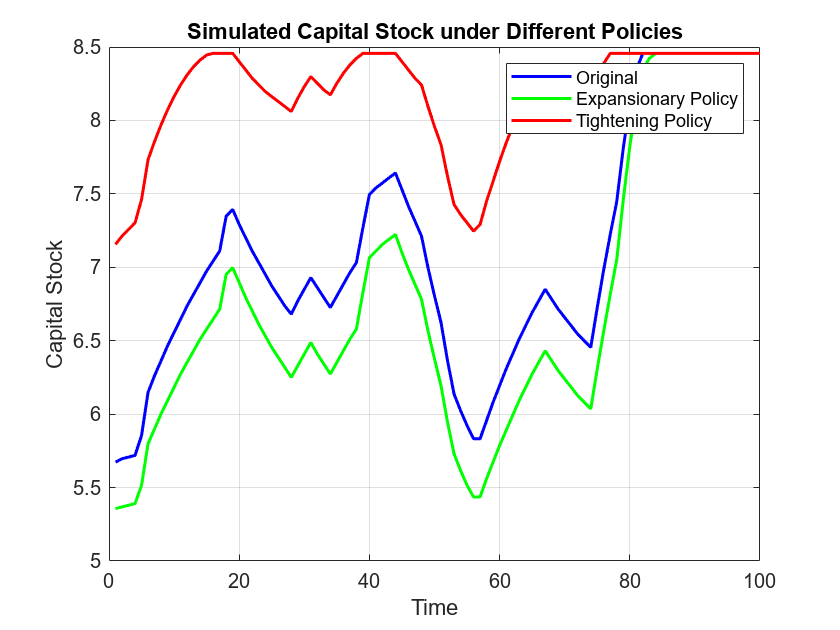

%% Compare Results

%% Capital 
figure;
plot(sim.ksim, 'b', 'LineWidth', 1.5); hold on;
plot(sim_expansion.ksim, 'g', 'LineWidth', 1.5); hold on;
plot(sim_tightening.ksim, 'r', 'LineWidth', 1.5);
legend('Original', 'Expansionary Policy', 'Tightening Policy');
title('Simulated Capital Stock under Different Policies');
xlabel('Time'); ylabel('Capital Stock');
grid on;
saveas(gcf, fullfile(figout, 'kcounter.png'));

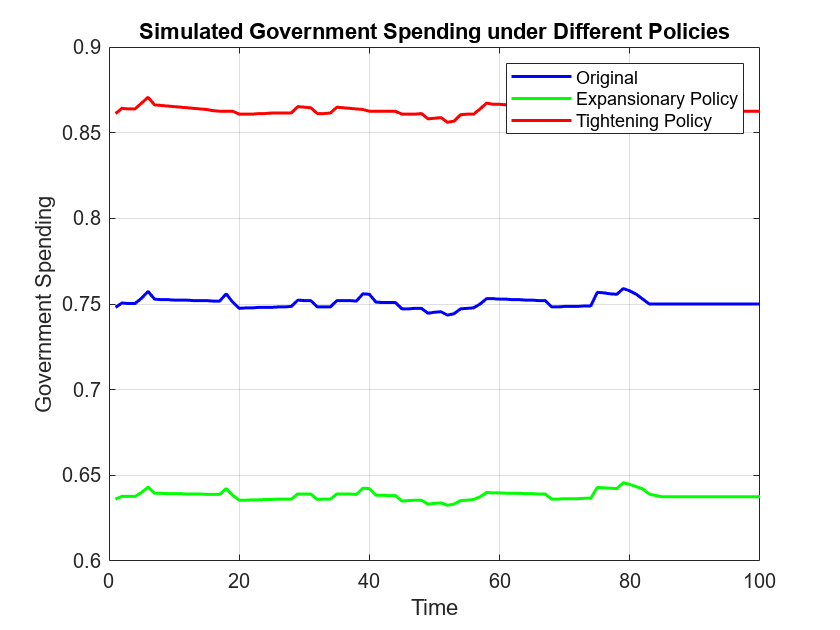


%% Government Spending
figure;
plot(sim.gsim, 'b', 'LineWidth', 1.5); hold on;
plot(sim_expansion.gsim, 'g', 'LineWidth', 1.5); hold on;
plot(sim_tightening.gsim, 'r', 'LineWidth', 1.5);
legend('Original', 'Expansionary Policy', 'Tightening Policy');
title('Simulated Government Spending under Different Policies');
xlabel('Time'); ylabel('Government Spending');
grid on;
saveas(gcf, fullfile(figout, 'gcounter.png'));

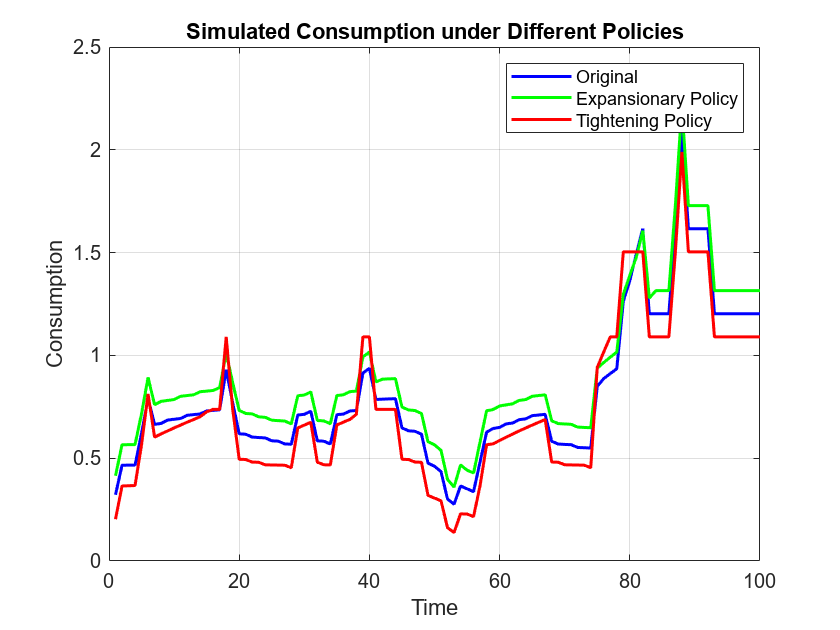

%% Consumption
figure;
plot(sim.csim, 'b', 'LineWidth', 1.5); hold on;
plot(sim_expansion.csim, 'g', 'LineWidth', 1.5); hold on;
plot(sim_tightening.csim, 'r', 'LineWidth', 1.5);
legend('Original', 'Expansionary Policy', 'Tightening Policy');
title('Simulated Consumption under Different Policies');
xlabel('Time'); ylabel('Consumption');
grid on;
saveas(gcf, fullfile(figout, 'ccounter.png'));

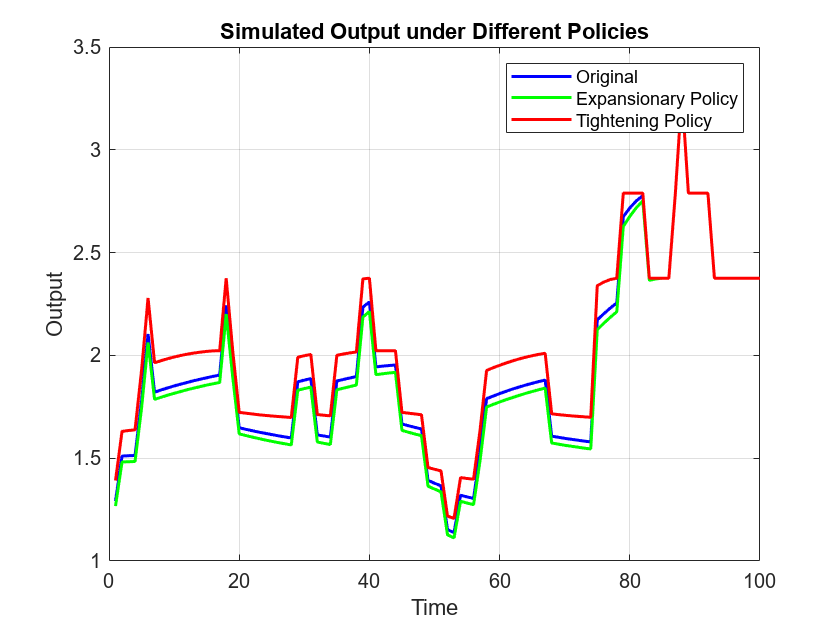

%% Output
figure;
plot(sim.ysim, 'b', 'LineWidth', 1.5); hold on;
plot(sim_expansion.ysim, 'g', 'LineWidth', 1.5); hold on;
plot(sim_tightening.ysim, 'r', 'LineWidth', 1.5);
legend('Original', 'Expansionary Policy', 'Tightening Policy');
title('Simulated Output under Different Policies');
xlabel('Time'); ylabel('Output');
grid on;
saveas(gcf, fullfile(figout, 'ycounter.png'));

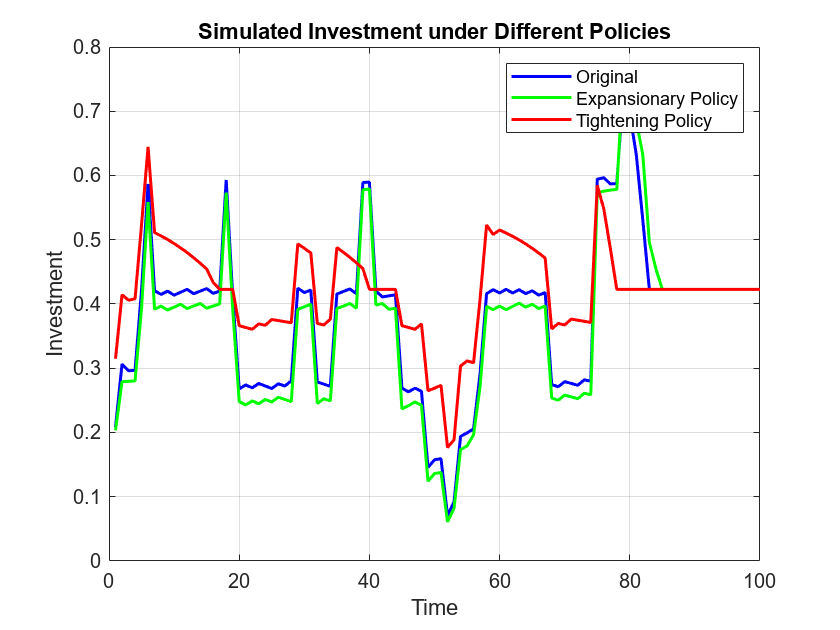

%% Investment
figure;
plot(sim.isim, 'b', 'LineWidth', 1.5); hold on;
plot(sim_expansion.isim, 'g', 'LineWidth', 1.5); hold on;
plot(sim_tightening.isim, 'r', 'LineWidth', 1.5);
legend('Original', 'Expansionary Policy', 'Tightening Policy');
title('Simulated Investment under Different Policies');
xlabel('Time'); ylabel('Investment');
grid on;
saveas(gcf, fullfile(figout, 'icounter.png'));

### Statistical Analysis of Simulated Variables

%% Compute statistics for original government spending
gsim_original = sim.gsim;
min_gsim_original = min(gsim_original);
max_gsim_original = max(gsim_original);
mean_gsim_original = mean(gsim_original);
median_gsim_original = median(gsim_original);
std_gsim_original = std(gsim_original);

%% Compute statistics for expansionary policy of government spending
gsim_expansion = sim_expansion.gsim;
min_gsim_expansion = min(gsim_expansion);
max_gsim_expansion = max(gsim_expansion);
mean_gsim_expansion = mean(gsim_expansion);
median_gsim_expansion = median(gsim_expansion);
std_gsim_expansion = std(gsim_expansion);

%% Compute statistics for tightening policy scenario of government spending
gsim_tightening = sim_tightening.gsim;
min_gsim_tightening = min(gsim_tightening);
max_gsim_tightening = max(gsim_tightening);
mean_gsim_tightening = mean(gsim_tightening);
median_gsim_tightening = median(gsim_tightening);
std_gsim_tightening = std(gsim_tightening);

% Create a table with results for government spending
T1 = table({'Original'; 'Expansionary'; 'Tightening'}, ...
    [min_gsim_original; min_gsim_expansion; min_gsim_tightening], ...
    [max_gsim_original; max_gsim_expansion; max_gsim_tightening], ...
    [mean_gsim_original; mean_gsim_expansion; mean_gsim_tightening], ...
    [median_gsim_original; median_gsim_expansion; median_gsim_tightening], ...
    [std_gsim_original; std_gsim_expansion; std_gsim_tightening], ...
    'VariableNames', {'Scenario', 'Min', 'Max', 'Mean', 'Median', 'StdDev'});

% Display table
disp(T1);

        Scenario          Min        Max       Mean      Median      StdDev  
    ________________    _______    _______    _______    _______    _________

    {'Original'    }    0.74349    0.75905    0.75068       0.75    0.0029642
    {'Expansionary'}    0.63252    0.64565    0.63811    0.63773    0.0024778
    {'Tightening'  }    0.85605    0.87065    0.86288     0.8625    0.0022775



### Create table for the remaining variables

%% Compute statistics and create tables
variables = {'Capital', 'Output', 'Consumption', 'Investment'};
data_original = [min(sim.ksim), max(sim.ksim), mean(sim.ksim), median(sim.ksim), std(sim.ksim);
                 min(sim.ysim), max(sim.ysim), mean(sim.ysim), median(sim.ysim), std(sim.ysim);
                 min(sim.csim), max(sim.csim), mean(sim.csim), median(sim.csim), std(sim.csim);
                 min(sim.isim), max(sim.isim), mean(sim.isim), median(sim.isim), std(sim.isim)];

data_expansion = [min(sim_expansion.ksim), max(sim_expansion.ksim), mean(sim_expansion.ksim), median(sim_expansion.ksim), std(sim_expansion.ksim);
                  min(sim_expansion.ysim), max(sim_expansion.ysim), mean(sim_expansion.ysim), median(sim_expansion.ysim), std(sim_expansion.ysim);
                  min(sim_expansion.csim), max(sim_expansion.csim), mean(sim_expansion.csim), median(sim_expansion.csim), std(sim_expansion.csim);
                  min(sim_expansion.isim), max(sim_expansion.isim), mean(sim_expansion.isim), median(sim_expansion.isim), std(sim_expansion.isim)];

data_tightening = [min(sim_tightening.ksim), max(sim_tightening.ksim), mean(sim_tightening.ksim), median(sim_tightening.ksim), std(sim_tightening.ksim);
                   min(sim_tightening.ysim), max(sim_tightening.ysim), mean(sim_tightening.ysim), median(sim_tightening.ysim), std(sim_tightening.ysim);
                   min(sim_tightening.csim), max(sim_tightening.csim), mean(sim_tightening.csim), median(sim_tightening.csim), std(sim_tightening.csim);
                   min(sim_tightening.isim), max(sim_tightening.isim), mean(sim_tightening.isim), median(sim_tightening.isim), std(sim_tightening.isim)];

T2 = table(variables', data_original(:,1), data_original(:,2), data_original(:,3), data_original(:,4), data_original(:,5), ...
    'VariableNames', {'Variable', 'Min', 'Max', 'Mean', 'Median', 'StdDev'});
T3 = table(variables', data_expansion(:,1), data_expansion(:,2), data_expansion(:,3), data_expansion(:,4), data_expansion(:,5), ...
    'VariableNames', {'Variable', 'Min', 'Max', 'Mean', 'Median', 'StdDev'});
T4 = table(variables', data_tightening(:,1), data_tightening(:,2), data_tightening(:,3), data_tightening(:,4), data_tightening(:,5), ...
    'VariableNames', {'Variable', 'Min', 'Max', 'Mean', 'Median', 'StdDev'});

% Display tables
disp('Statistics for Original Scenario:');

Statistics for Original Scenario:


disp(T2);

       Variable          Min         Max       Mean      Median     StdDev 
    _______________    ________    _______    _______    _______    _______

    {'Capital'    }      5.6738     8.4569     7.0983       6.89    0.83141
    {'Output'     }      1.1376      3.275     1.9285     1.8663    0.42576
    {'Consumption'}     0.27596     2.1022    0.80339    0.70773    0.35213
    {'Investment' }    0.070993    0.73454     0.3806    0.41719    0.12303



disp('Statistics for Expansionary Policy:');

Statistics for Expansionary Policy:


disp(T3);

       Variable          Min         Max       Mean      Median     StdDev 
    _______________    ________    _______    _______    _______    _______

    {'Capital'    }       5.357     8.4569      6.769     6.4714    0.95962
    {'Output'     }      1.1124      3.275      1.899     1.8276    0.43296
    {'Consumption'}     0.35955     2.2147    0.89915    0.80241    0.34923
    {'Investment' }    0.060811    0.75999    0.36726    0.39456    0.13201



disp('Statistics for Tightening Policy:');

Statistics for Tightening Policy:


disp(T4);

       Variable          Min        Max       Mean      Median      StdDev 
    _______________    _______    _______    _______    _______    ________

    {'Capital'    }     7.1559     8.4569     8.1707     8.2929     0.36485
    {'Output'     }     1.2073      3.275     2.0177     1.9985     0.40211
    {'Consumption'}    0.13806     1.9897    0.73949    0.66095     0.37372
    {'Investment' }    0.17678    0.64459    0.42046    0.42285    0.073512

